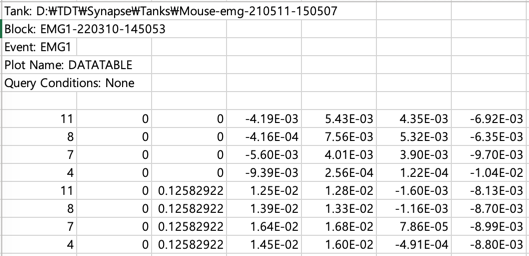

reader = channelReader();

tic 
%                            
reader.readMultiChannelFile( ...
    "./data/height1 - 1,10s - 2x.xlsx", ...#filename
    1, ...#channelColumnIdx
    3, ...#timeColumnIdx
    7, ...#startRowIdx
    4, ...#startColIdx
    nan ... #sample frequency. time column이 있으면 자동으로 frequency 계산하므로 nan을 입력
    ); %일단 파일을 불러옴
toc % 코드 실행 시간 측정. 오래 걸림.
%                            organoid, channel, month 


#### 1. 특정 시간 구간의 signal만 사용하기

emg = reader.readSingleChannelFromFile(1, 8, 1);

(optional)

20-200hz 구간만 남기고 지움(Classification of Five Finger Movement, based on a Low-cost, Real-time EMG System)

emg.bandPass([20,200])


emg.cutTime([10,20]);

fgfgfg

fgfg

emg.rectify();

plot(emg.t, emg.raw)
plot(emg.t, emg.signalRawRectified)
plot(emg.t, emg.signalFilteredRectified)

dfdf

matlab signal processing toolbox 설치 필요

Computes the RMS-envelope, the MA-envelope ot the LE-envelope of an EMG signal.

emg.envelope(1000);
plot(emg.t, emg.signalRawEnveloped)
plot(emg.t, emg.signalFilteredEnveloped)

length(emg.signalFilteredEnveloped)

%                                 organoid, month
pixels = reader.readManyChannelsFromFile(1, 1);
pixels.keys

sampling rate가 모두 똑같은 상황을 가정하고 코드를 짰음


%                      nrow, ncol
ani = timeVaryingHeatmapEMG(2,2); % timeVaryingHeatmap 오브젝트 생성. pixel들이 2*2 배열로 되어 있다고 가정.

%  이 pixel의 row번호, column번호, pixel에 mapping할 channel 번호
ani.addPixel(1, 1, pixels(4) );


 In the (1, 1)th slot, added channel 4 


ani.addPixel(1, 2, pixels(7) );


 In the (1, 2)th slot, added channel 7 


ani.addPixel(2, 1, pixels(8) );


 In the (2, 1)th slot, added channel 8 


ani.addPixel(2, 2, pixels(11));


 In the (2, 2)th slot, added channel 11 




ani.cutTime([10,20]);


cutting the time of (1, 1)th element = channel 4
new startTime = 9.999483
new endTime = 20.000932
new duration = 10.001449
new nTimestamp = 10175

cutting the time of (1, 2)th element = channel 7
new startTime = 9.999483
new endTime = 20.000932
new duration = 10.001449
new nTimestamp = 10175

cutting the time of (2, 1)th element = channel 8
new startTime = 9.999483
new endTime = 20.000932
new duration = 10.001449
new nTimestamp = 10175

cutting the time of (2, 2)th element = channel 11
new startTime = 9.999483
new endTime = 20.000932
new duration = 10.001449
new nTimestamp = 10175


step size = 102 timestamps = 100.270080 miliseconds
Total 99 steps
max signal value = 0.062012, ColorLimits is set w.r.t this value.

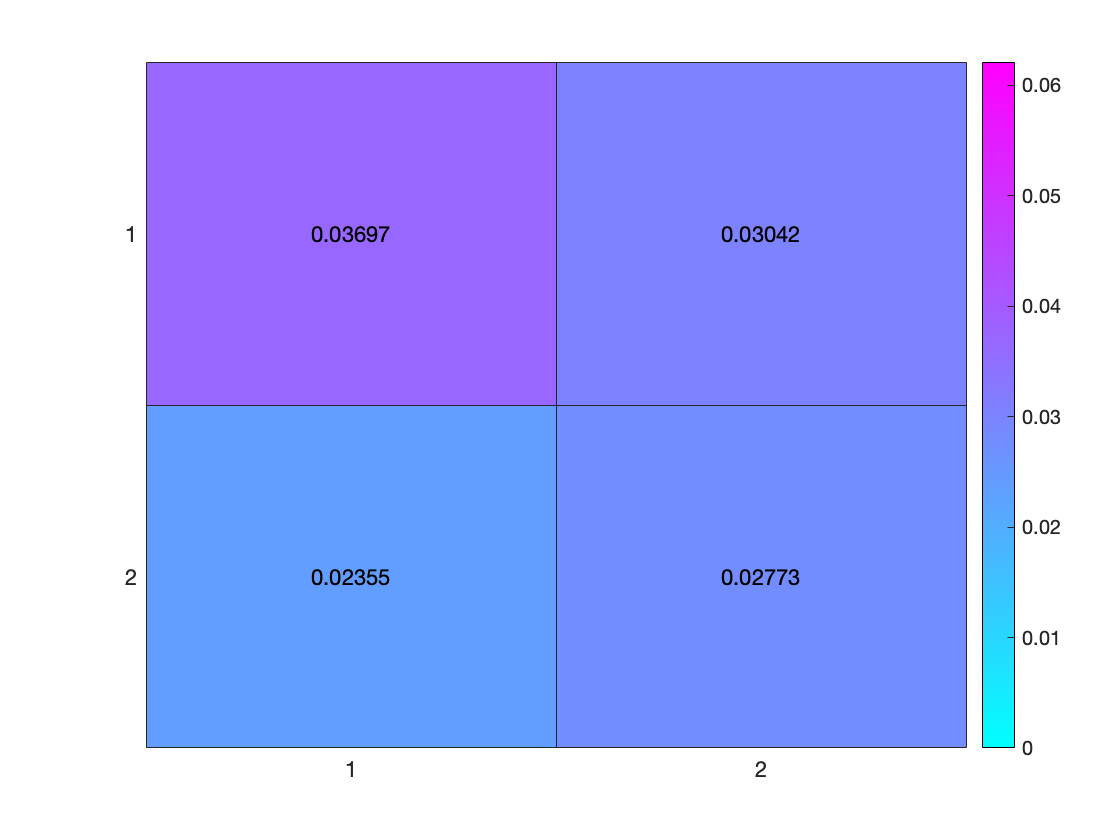

ani.bandPass([20, 200])
ani.rectify()      % 모든 channel에 일괄적으로 rectification 적용
ani.envelope(1000) % 모든 channel에 일괄적으로 rms enveloping 적용 


%                           
ani.makeTimeVaryingHeatmap( ...
    100, ... % 시간 간격(millisecond)
    true, ... % filterd or not
    cool) %colormap

step size = 1017 timestamps = 999.751682 miliseconds
Total 10 steps
max signal value = 0.062012, ColorLimits is set w.r.t this value.

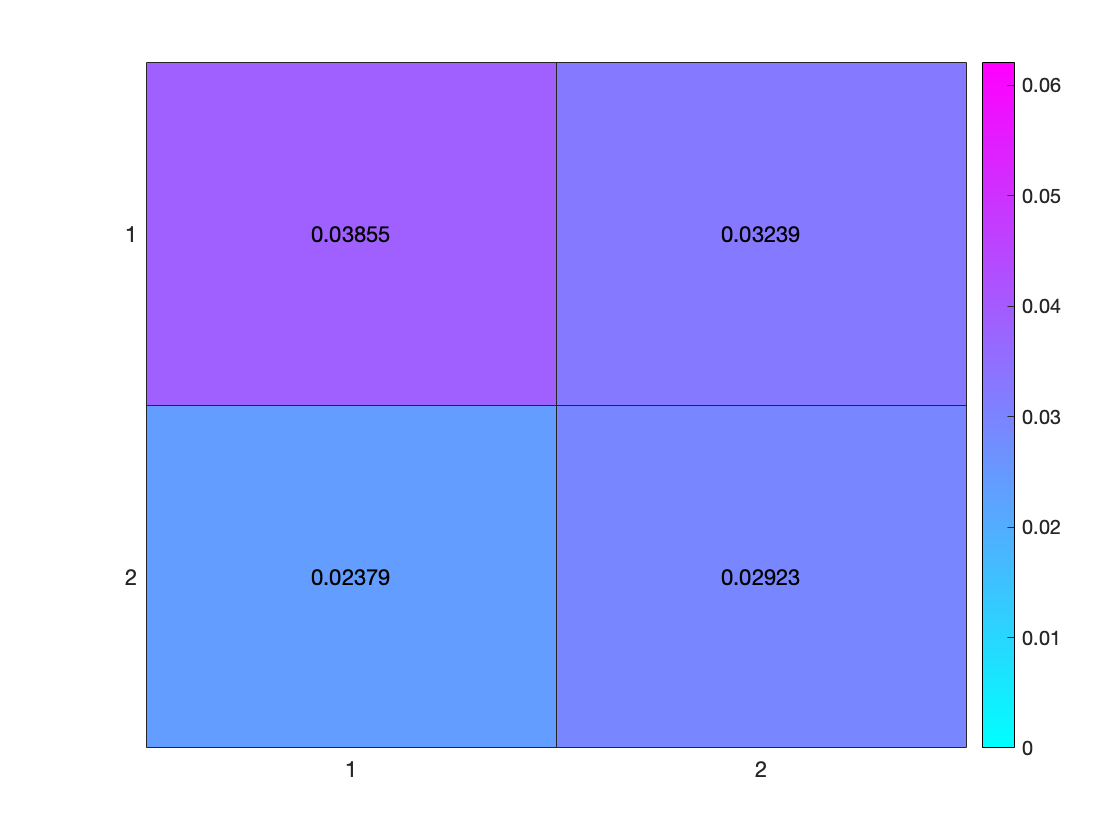

time interval을 milisecond 단위로 입력ㅅ

true